# Demo File

## Data Import

https://www.kaggle.com/datasets/shiratorizawa/ncarcsv2

**Content**

The datset contains atmospheric variables over different latitude and longitude starting from year 1948 to 2018. Details about the variables can be found [at NCAR website](https://psl.noaa.gov/data/gridded/data.ncep.reanalysis.html). There are 21 features. They are,

- lat : Latitude

- lon : Longitude

- time : Dates

- slp : Mean sea level pressure

- uwnd-x, uwnd-y and uwnd : U-wind

- vwnd-x, vwnd-y and vwnd : V-wind

- tmp-x, tmp-y and tmp : Temperature

- omega-x, omega-y and omega : Vertical Wind velocity

- rhum-x, rhum-y and rhum : relative humidity

- pr-wtr : Precipitable water

- rain : Rainfall

rainData = importRainData('finalDatasetWithRain.csv')

rainData = 622392×21 table
    lat    lon       time        omega_x      omega_y         omega       pr_wtr    rhum_x    rhum_y    rhum        slp        tmp_x    tmp_y      tmp      uwnd_x    uwnd_y    uwnd     vwnd_x      vwnd_y        vwnd      rain 
    ___    ___    __________    _________    __________    ___________    ______    ______    ______    _____    __________    _____    ______    ______


% Plot the original rain data

rainData(rainData.rain == -9999, :) = []; % Remove rows with -9999 values

## Data Cleaning and Preprocessing

% We've got some cleanup to do!!
% Use the interactive table to sort by time. Then copy the code necessary
% here.
rainData = sortrows(rainData, "time", "descend");

% Replace any "-9999" values with NaN 
% Or remove any rows with missing data with rmmissing if there are blanks


% Plot the original rain data


## Timetable Conversion

% convert table to timetable

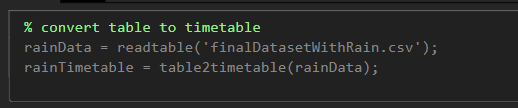

rainTimetable = table2timetable(rainData) % automatically finds/detects the time column!!!

rainTimetable = 544593×20 timetable
       time        lat       lon      omega_x    omega_y    omega    pr_wtr    rhum_x    rhum_y    rhum        slp        tmp_x    tmp_y      tmp      uwnd_x    uwnd_y       uwnd       vwnd_x    vwnd_y     vwnd     rain
    __________    ______    ______    _______    _______    _____    ______    ______    ______    _____    __________    _____    ______    ______  


% retime timetable with live task

% Retime timetable
newTimetable = retime(rainTimetable,"regular","mean",TimeStep=calquarters(1))

newTimetable = 284×20 timetable
       time        lat       lon        omega_x       omega_y        omega      pr_wtr    rhum_x    rhum_y     rhum        slp        tmp_x    tmp_y      tmp       uwnd_x     uwnd_y       uwnd       vwnd_x       vwnd_y       vwnd         rain  
    __________    ______    ______    ___________    __________    _________    ______    ______    ______    ______    __________    _____    ______


% Plot the original rain data


% I didn't know the best way to retime the data so that I could see
% patterns. So I quickly switched between yearly, monthly, and quarterly.
% Yearly seemed a little too course, but quarterly seemed to reflect some
% seasonality to my untrained eyes. Is it even valid to average this way?
% Did I erase too much data or create false artifacts? That's what the
% expert scientists need to decide!

## General Data Exploration

% Because MATLAB can handle this data amount of data easily, let's go back to the 
% original timetable data without any averaging. I've decided not to consider 
% seasonality in predicting rainfall.

rainData = RainDemoClassAssign(rainData); % custom function for classifying weather
% Open the function to check it out.

rainData.weathercat = categorical(rainData.weathercat);

rainData(isnan(rainData.rain),:) = [];

## Classification Model Training

% Optional: Clean outliers (this can also get rid of the -9999's)

Use an interactive workflow to test different machine learning models with the Classification Learner App. The app will include default values for validation and testing that you can change. 

% Launch the classification learner app
classificationLearner

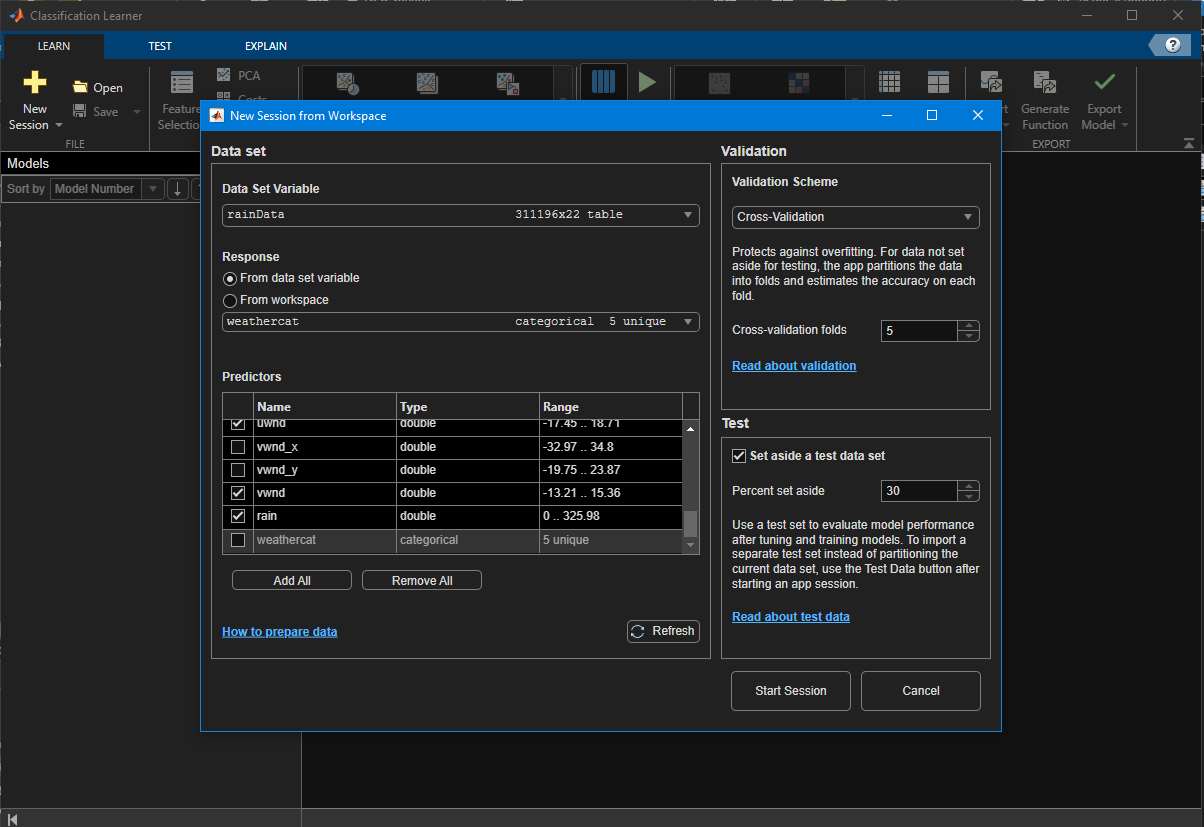

Notice that you can enable training in parallel if you have the resources. "All quick to train" models is a good choice for quickly assessing potential classification models and methods. Once your model is trained, you can see how it performed with a confusion matrix. A confusion matrix compares the data's true class (in this case, the type of weather: clear, rainy, stormy, humid, or fair in this example) vs. what the model predicted.

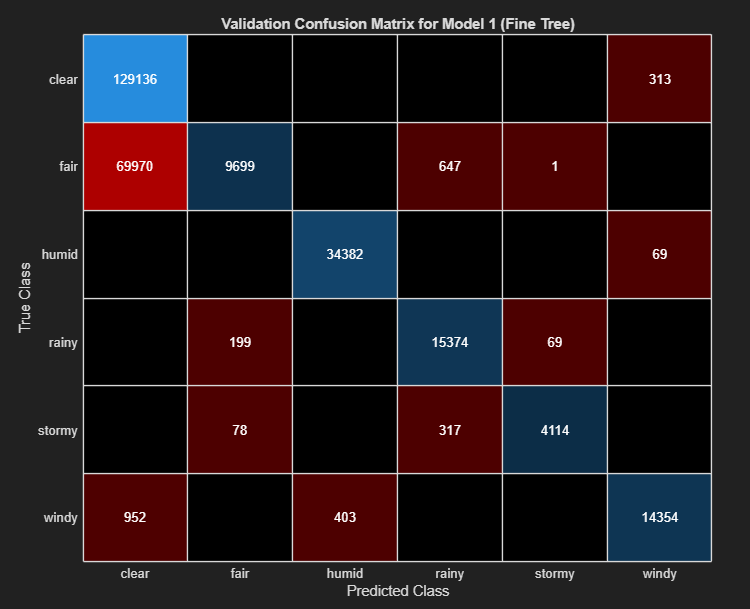

Once you are satisfied with your model, you can export the trained model and choose whether or not to include the original training data in the exported model. Including the data increases the transparency of the model to others, who may want to see your data and process. Removing the data decreases the size of the trained model file, making it easier to share and deploy.

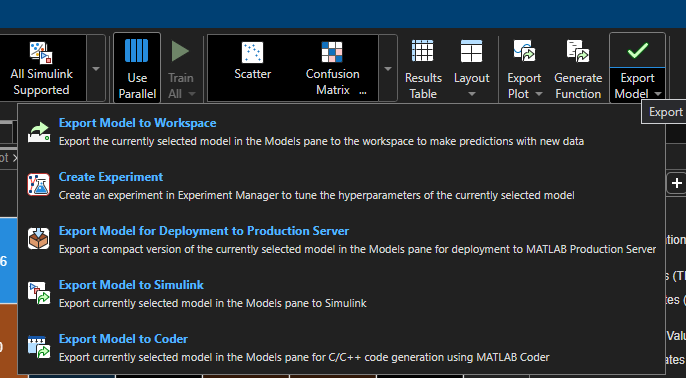

If you've exported your trained model to the MATLAB workspace, you can now save the trained model structure as a .mat file.

save("trainedModel.mat","trainedModel"); % or right click on the variable and save

Error using save
Variable 'trainedModel' not found.

You can then load the model and use it to classify new datasets.

## Additional Data Acquisition

### ThingSpeak

### MATLAB Mobile

% now you can use the pretrained model to predict if it's gonna rain/how
% much in Natick, MA, where our sensor is.

% access ThingSpeak channel from Natick 
data = thingSpeakRead(12397,NumPoints=3,OutputFormat='TimeTable')

% retrieve recent weather data
% variables: temperature, humidity, windspeed

% run trained model to determine raining


% validate

